# Spline orden 5, Matricial x 4 Puntos (theta2)

% puntos para spline, en tiemp de 1 a 4
Puntos=([(1:4)',theta2'])';
Puntos=Puntos(:);



## Construcción de matríz característica

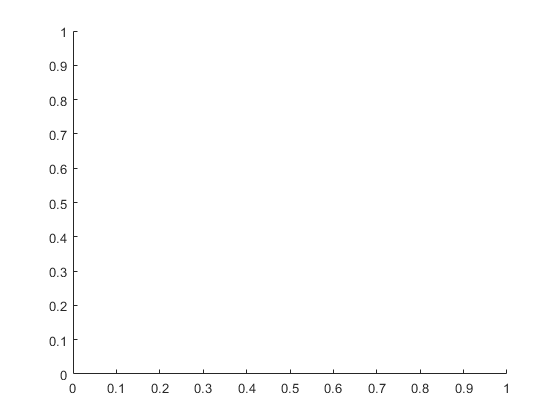

A0=[Puntos(1)^5,Puntos(1)^4,Puntos(1)^3,Puntos(1)^2,Puntos(1),1;Puntos(3)^5,Puntos(3)^4,Puntos(3)^3,Puntos(3)^2,Puntos(3),1];
A1=[Puntos(3)^5,Puntos(3)^4,Puntos(3)^3,Puntos(3)^2,Puntos(3),1;Puntos(5)^5,Puntos(5)^4,Puntos(5)^3,Puntos(5)^2,Puntos(5),1];
A2=[Puntos(5)^5,Puntos(5)^4,Puntos(5)^3,Puntos(5)^2,Puntos(5),1;Puntos(7)^5,Puntos(7)^4,Puntos(7)^3,Puntos(7)^2,Puntos(7),1];

A11=[5*Puntos(3)^4,4*Puntos(3)^3,3*Puntos(3)^2,2*Puntos(3),1,0,-5*Puntos(3)^4,-4*Puntos(3)^3,-3*Puntos(3)^2,-2*Puntos(3),-1,0];
A12=[5*Puntos(5)^4,4*Puntos(5)^3,3*Puntos(5)^2,2*Puntos(5),1,0,-5*Puntos(5)^4,-4*Puntos(5)^3,-3*Puntos(5)^2,-2*Puntos(5),-1,0];

A111=[20*Puntos(3)^3,12*Puntos(3)^2,6*Puntos(3),2,0,0,-20*Puntos(3)^3,-12*Puntos(3)^2,-6*Puntos(3),-2,0,0];
A222=[20*Puntos(5)^3,12*Puntos(5)^2,6*Puntos(5),2,0,0,-20*Puntos(5)^3,-12*Puntos(5)^2,-6*Puntos(5),-2,0,0];

A=[A0,0*A0,0*A0;0*A0,A1,0*A0;A0*0,A0*0,A2;A11,0,0,0,0,0,0;0,0,0,0,0,0,A12;A111,0,0,0,0,0,0;0,0,0,0,0,0,A222];


A=[A;5*Puntos(1)^4,4*Puntos(1)^3,3*Puntos(1)^2,2*Puntos(1),1,0,0,0,0,0,0,0,0,0,0,0,0,0];
A=[A;5*Puntos(3)^4,4*Puntos(3)^3,3*Puntos(3)^2,2*Puntos(3),1,0,0,0,0,0,0,0,0,0,0,0,0,0];
A=[A;20*Puntos(1)^3,12*Puntos(1)^2,6*Puntos(1),2,0,0,0,0,0,0,0,0,0,0,0,0,0,0];
A=[A;20*Puntos(3)^3,12*Puntos(3)^2,6*Puntos(3),2,0,0,0,0,0,0,0,0,0,0,0,0,0,0];

A=[A;0,0,0,0,0,0,5*Puntos(5)^4,4*Puntos(5)^3,3*Puntos(5)^2,2*Puntos(5),1,0,0,0,0,0,0,0];
A=[A;0,0,0,0,0,0,0,0,0,0,0,0,5*Puntos(7)^4,4*Puntos(7)^3,3*Puntos(7)^2,2*Puntos(7),1,0];
A=[A;0,0,0,0,0,0,20*Puntos(5)^3,12*Puntos(5)^2,6*Puntos(5),2,0,0,0,0,0,0,0,0];
A=[A;0,0,0,0,0,0,0,0,0,0,0,0,20*Puntos(7)^3,12*Puntos(7)^2,6*Puntos(7),2,0,0];

b=[Puntos(2);Puntos(4);Puntos(4);Puntos(6);Puntos(6);Puntos(8);0;0;0;0;0;0;0;0;0;0;0;0];

hold off

solv=A\b;

## Graficar y obtener tramos de polinomio

Para cada tramo encontrado en la solución, escribir el polinomio

entre los dos puntos del tramo correspondiente, con separacion 0.05

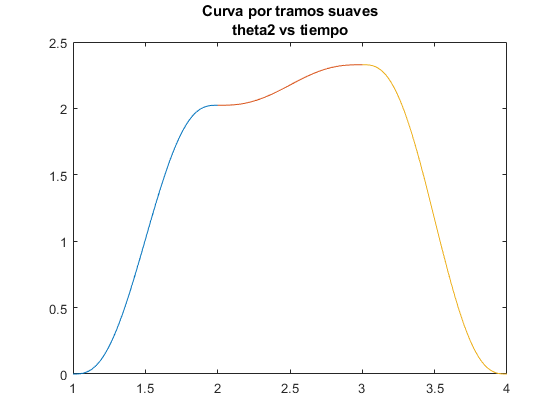

separacion=0.01;
x=Puntos(1):separacion:(Puntos(3));
y=solv(1)*x.^5+solv(2)*x.^4+solv(3)*x.^3+solv(4)*x.^2+solv(5)*x+solv(6);
plot(x,y)
hold on

x1=Puntos(3):separacion:Puntos(5);
y1=solv(7)*x1.^5+solv(8)*x1.^4+solv(9)*x1.^3+solv(10)*x1.^2+solv(11)*x1+solv(12);
plot(x1,y1)
 
x2=Puntos(5):separacion:Puntos(7);
y2=solv(13)*x2.^5+solv(14)*x2.^4+solv(15)*x2.^3+solv(16)*x2.^2+solv(17)*x2+solv(18);
plot(x2,y2)

s5_X2=[x,x1(2:end-1),x2];
s5_Y2=[y,y1(2:end-1),y2];
title({'Curva por tramos suaves';'theta2 vs tiempo'})
hold off

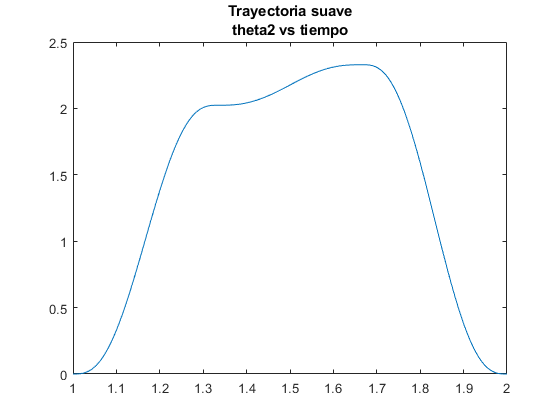

plot(linspace(Puntos(1),Puntos(3),length(s5_Y2)),s5_Y2)
title({'Trayectoria suave';'theta2 vs tiempo'})

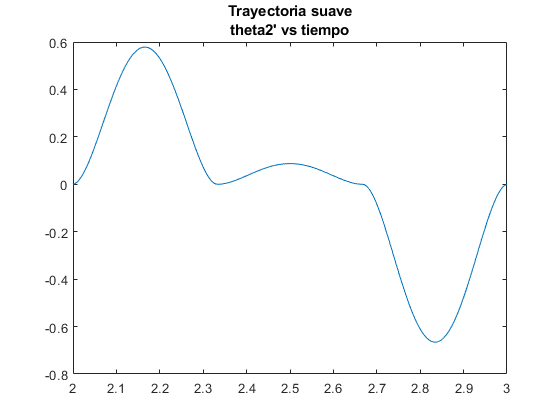


factor=length((1:4)')/length(Y1);
plot(linspace(Puntos(3),Puntos(5),length(s5_Y2)-1),diff(s5_Y2)/factor)
title({'Trayectoria suave';"theta2' vs tiempo"})

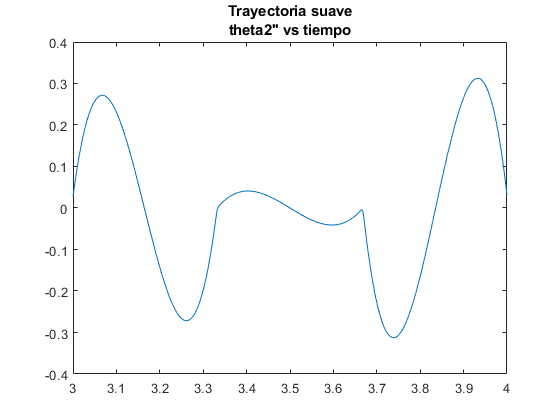


plot(linspace(Puntos(5),Puntos(7),length(s5_Y2)-2),diff(diff(s5_Y2))/(factor^2))
title({'Trayectoria suave';"theta2'' vs tiempo"})

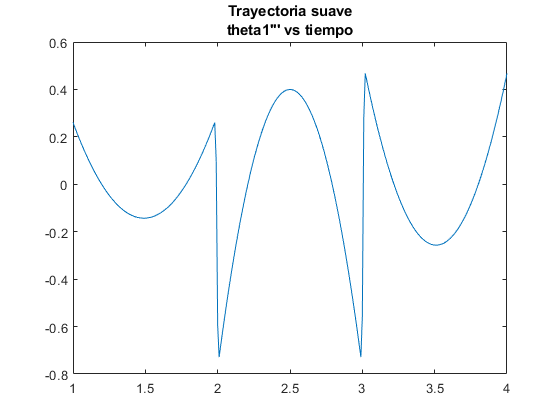


plot(linspace(Puntos(1),Puntos(7),length(s5_Y1)-3),diff(diff(diff(s5_Y1)))/(factor^3))
title({'Trayectoria suave';"theta1''' vs tiempo"})

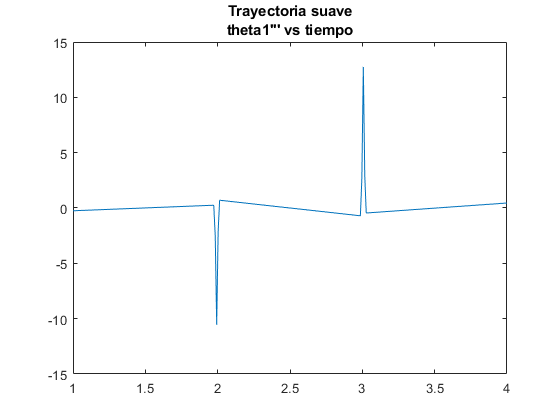


plot(linspace(Puntos(1),Puntos(7),length(s5_Y1)-4),diff(diff(diff(diff(s5_Y1))))/(factor^4))
title({'Trayectoria suave';"theta1''' vs tiempo"})




% Programado por: Alfredo José Maussa Caballero.